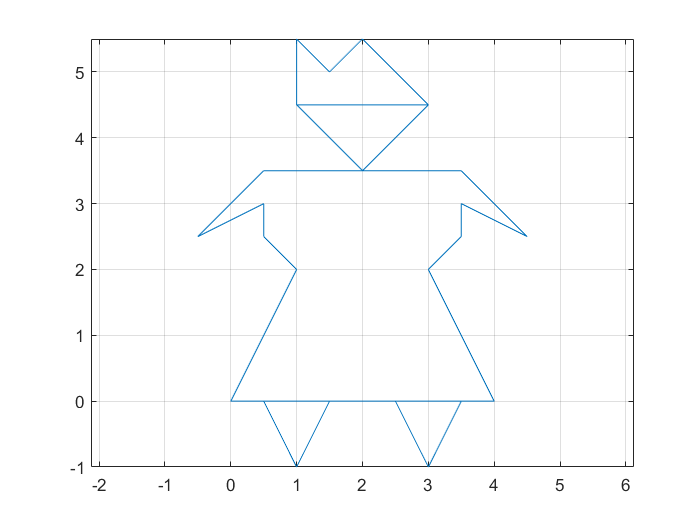

% MP1 - GRUPP 10
clear

X = [0 1 0.5 0.5 -0.5 0.5 2 1 3 2.5 2 1.5 1 1 3 2 3.5 4.5 3.5 3.5 3 4 2.5 3 3.5 0.5 1 1.5 0;   
     0 2 2.5 3 2.5 3.5 3.5 4.5 4.5 5 5.5 5 5.5 4.5 4.5 3.5 3.5 2.5 3 2.5 2 0 0 -1 0 0 -1 0 0]; 
  
clf
plot(X(1,:),X(2,:),'-')

grid on
xlim([-2,5])
axis equal

% SKALNING

a = 2; % skalfaktor i x-led
b = 2; % skalfaktor i y-led
F = [a 0; 0 b];
% Multiplicating the matrix with the 
Y = F*X; 

[P,O] = eig(F)

P =      1     0
     0     1


O =      2     0
     0     2


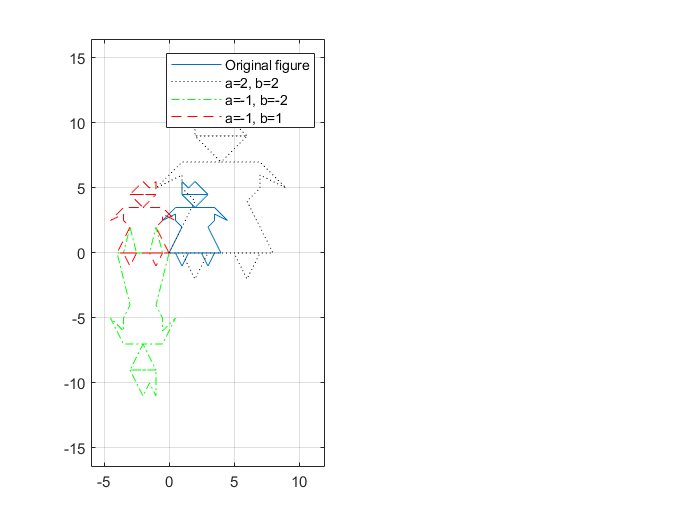



a = -1; % skalfaktor i x-led
b = -2; % skalfaktor i y-led
F = [a 0; 0 b];
% Multiplicating the matrix with the 
Z = F*X; 

a = -1; % skalfaktor i x-led
b = 1; % skalfaktor i y-led
F = [a 0; 0 b];
% Multiplicating the matrix with the 
D = F*X; 

% Vänster figur

subplot(1,2,1)
plot(X(1,:),X(2,:),'-', Y(1,:),Y(2,:),'k:', Z(1,:),Z(2,:),'g-.', D(1,:),D(2,:),'r--')
legend("Original figure", "a=2, b=2", "a=-1, b=-2", "a=-1, b=1")

grid on
xlim([-6,12])
ylim([-13,17])
axis equal

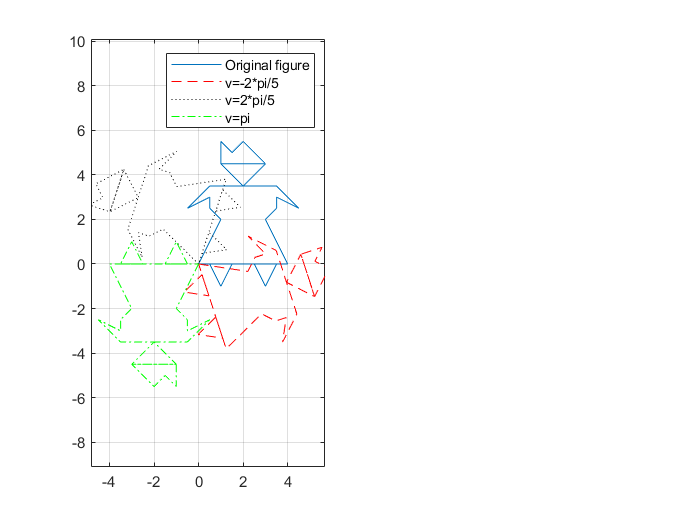

xl = xlim;
yl = ylim;

% s är egenvektorer, normerade?
% d är egenvärden, beskriver skalfaktorn i x respektive y-led


% ROTATION

v = -2*pi/5;
R = [cos(v) -sin(v); sin(v) cos(v)];

Y = R*X;


v = 2*pi/5;
R = [cos(v) -sin(v); sin(v) cos(v)];

D = R*X;

v = pi;
R = [cos(v) -sin(v); sin(v) cos(v)];
Z = R*X;

% Vänster figur
clf



subplot(1,2,1)
plot(X(1,:),X(2,:),'-', Y(1,:),Y(2,:),'r--', D(1,:),D(2,:),'k:', Z(1,:),Z(2,:),'g-.')
legend("Original figure", "v=-2*pi/5","v=2*pi/5", "v=pi")
grid on
xlim([-5.5,5])
ylim([-5.5,6])
axis equal

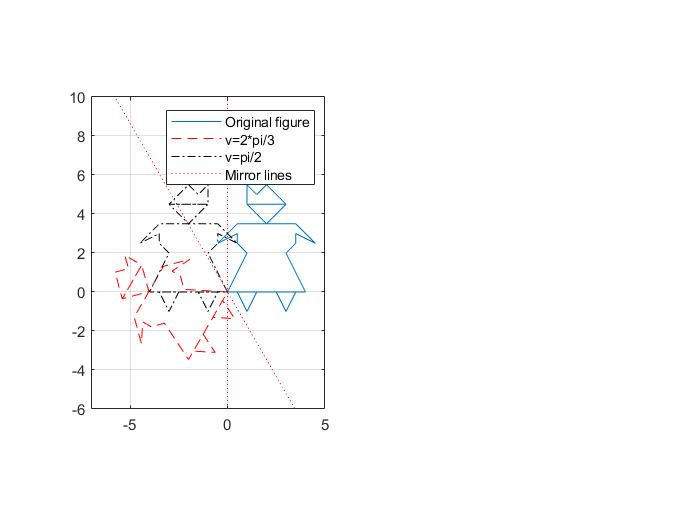

xl = xlim;
yl = ylim;




% SPEGLING
v = 2*pi/3;
S = [cos(2*v) sin(2*v); sin(2*v) -cos(2*v)];

Y = S*X;
v = pi/2;
S = [cos(2*v) sin(2*v); sin(2*v) -cos(2*v)];

Z = S*X;

x= linspace(-10,10);
y = tan(2*pi/3)*x;

% Vänster figur
clf
subplot(1,2,1)
plot(X(1,:),X(2,:),'-',Y(1,:),Y(2,:),'r--',Z(1,:),Z(2,:),'k-.',[0 0], [-10 10], 'r:', x,y,'r:')
legend("Original figure", "v=2*pi/3", "v=pi/2", "Mirror lines")
grid on
xlim([-8,6])
ylim([-8,6])

axis equal

subplot(1,2,1)
xlim([-7 5])
ylim([-6 10])

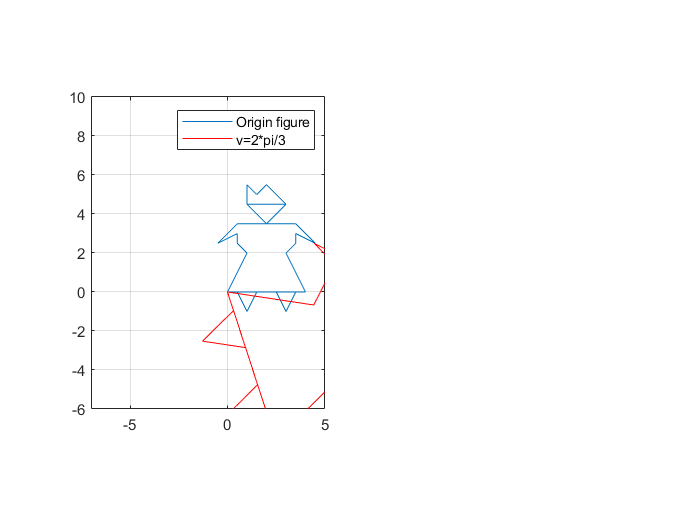



% SPEGLING
a = 2; % skalfaktor i x-led
b = 2; % skalfaktor i y-led
F = [a 0; 0 b];
% Multiplicating the matrix with the 

v = -2*pi/5;
R = [cos(v) -sin(v); sin(v) cos(v)];

Y = F*R*X; 

% Vänster figur
clf
subplot(1,2,1)
plot(X(1,:),X(2,:),'-',Y(1,:),Y(2,:),'r-')
legend("Origin figure", "v=2*pi/3")
grid on
xlim([-8,6])
ylim([-8,6])

axis equal

subplot(1,2,1)
xlim([-7 5])
ylim([-6 10])